# `Data Preparation for analysis with:`

# 2.2 Multisine excitation with a full frequency grid)

#### Using estimation Data Level_1 and validation data Level_2 MIMO System) 

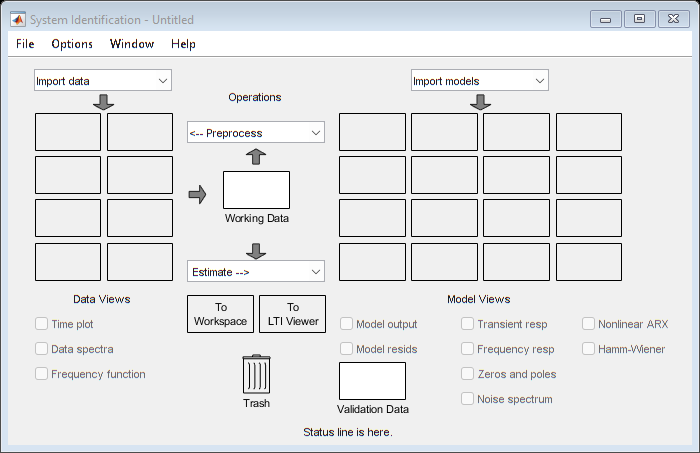

clear;
% Parameters
N = length(ESTIM.Force); % Number of samples
Fs = ESTIM.Fs;           % Sampling frequency
Ts = 1/Fs;               % Sampling time
t = (0:N-1) * Ts;        % Time vector -- in case iddata objects created will not be used

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%iddata Objects for System Identification%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Estimation data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Force and Voltage as inputs
inputs = [ESTIM.Force; ESTIM.Voltage]';

% Acceleration in X, Y, Z as outputs
outputs = [ESTIM.Acceleration(1,:); ESTIM.Acceleration(2,:); ESTIM.Acceleration(3,:)]';

% iddata object
data_Estimation = iddata(outputs, inputs, Ts);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Validation data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
inputs_Val = [VALID.Force; VALID.Voltage]';
outputs_Val = [VALID.Acceleration(1,:); VALID.Acceleration(2,:); VALID.Acceleration(3,:)]';

% iddata object
data_Validation = iddata(outputs_Val, inputs_Val, Ts);

systemIdentification

#### Using estimation Data Level_3 and validation data Level_2 MISO)

`case: (1) where measurements are being taken at the excitation point location on the aircraft)`

clear;
ESTIM = load('F16Data_FullMSine_Level3.mat'); 
VALID = load('F16Data_FullMSine_Level2_Validation.mat'); 


% Parameters
N = length(ESTIM.Force); % Number of samples
Fs = ESTIM.Fs;           % Sampling frequency
Ts = 1/Fs;               % Sampling time
t = (0:N-1) * Ts;        % Time vector -- in case iddata objects created will not be used

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%iddata Objects for System Identification%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Estimation data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Force and Voltage as inputs
inputs = [ESTIM.Force; ESTIM.Voltage]';

% Acceleration in X, Y, Z as outputs
outputs = [ESTIM.Acceleration(1,:)]';

% iddata object
data_Estimation = iddata(outputs, inputs, Ts);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Validation data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
inputs_Val = [VALID.Force; VALID.Voltage]';
outputs_Val = [VALID.Acceleration(1,:)]';

% iddata object
data_Validation = iddata(outputs_Val, inputs_Val, Ts);
systemIdentification

#### Using estimation Data Level_5 and validation data Level_4 MISO)

`case: (1) where measurements are being taken at the excitation point location on the aircraft)`

clear;
ESTIM = load('F16Data_FullMSine_Level5.mat'); 
VALID = load('F16Data_FullMSine_Level4_Validation.mat'); 


% Parameters
N = length(ESTIM.Force); % Number of samples
Fs = ESTIM.Fs;           % Sampling frequency
Ts = 1/Fs;               % Sampling time
t = (0:N-1) * Ts;        % Time vector -- in case iddata objects created will not be used

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%iddata Objects for System Identification%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Estimation data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Force and Voltage as inputs
inputs = [ESTIM.Force; ESTIM.Voltage]';

% Acceleration in X, Y, Z as outputs
outputs = [ESTIM.Acceleration(1,:)]';

% iddata object
data_Estimation = iddata(outputs, inputs, Ts);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Validation data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
inputs_Val = [VALID.Force; VALID.Voltage]';
outputs_Val = [VALID.Acceleration(1,:)]';

% iddata object
data_Validation = iddata(outputs_Val, inputs_Val, Ts);

systemIdentification

#### Using estimation Data Level_7 and validation data Level_6 MISO)

`case: (1) where measurements are being taken at the excitation point location on the aircraft)`

clear; 
ESTIM = load('F16Data_FullMSine_Level7.mat'); 
VALID = load('F16Data_FullMSine_Level6_Validation.mat'); 


% Parameters
N = length(ESTIM.Force); % Number of samples
Fs = ESTIM.Fs;           % Sampling frequency
Ts = 1/Fs;               % Sampling time
t = (0:N-1) * Ts;        % Time vector -- in case iddata objects created will not be used

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%iddata Objects for System Identification%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Estimation data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Force and Voltage as inputs
inputs = [ESTIM.Force; ESTIM.Voltage]';

% Acceleration in X, Y, Z as outputs
outputs = [ESTIM.Acceleration(1,:)]';

% iddata object
data_Estimation = iddata(outputs, inputs, Ts);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Validation data %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
inputs_Val = [VALID.Force; VALID.Voltage]';
outputs_Val = [VALID.Acceleration(1,:)]';

% iddata object
data_Validation = iddata(outputs_Val, inputs_Val, Ts);
systemIdentification